DD = vehicleDetectorYOLOv2;

v_reader = VideoReader("caltech_cordova1.avi")

v_reader =   VideoReader with properties:

   General Properties:
            Name: 'caltech_cordova1.avi'
            Path: 'C:\Program Files\MATLAB\R2025b\toolbox\driving\core\drivingdata'
        Duration: 8.3333
     CurrentTime: 0
       NumFrames: 250

   Video Properties:
           Width: 640
          Height: 480
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


v_writer = VideoWriter("output.avi")

v_writer =   VideoWriter

    General Properties:

       Filename:                 'output.avi'
       Path:                     'C:\Users\aryan\Downloads\ComputerVisionForScienceAndEngineering'
       FileFormat:               'avi'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


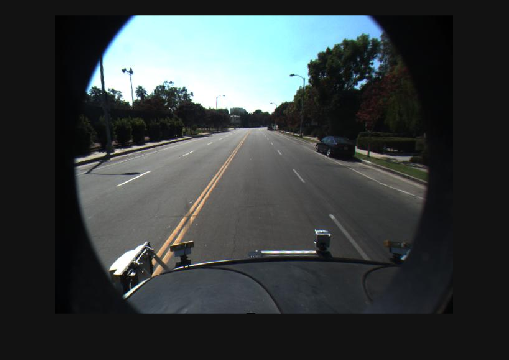


% frame = readFrame(v_reader);

frameNo = 90;
frame = read(v_reader, frameNo);

[bboxes, scores] = detect(DD, frame);

imshow(frame);

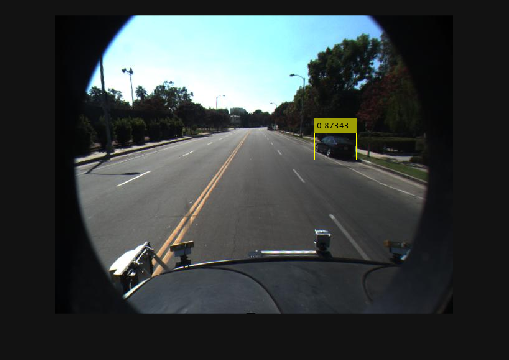

if ~isempty(bboxes)
    frame = insertObjectAnnotation(frame, "rectangle", bboxes, scores);
end
imshow(frame)

open(v_writer)
while hasFrame(v_reader)
frame = readFrame(v_reader);
[bboxes, scores] = detect(DD, frame);
if ~isempty(bboxes)
    frame = insertObjectAnnotation(frame, "rectangle", bboxes, scores);
end
% imshow(frame)
writeVideo(v_writer, frame)
end
close(v_writer)

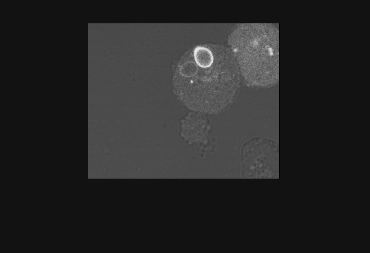

v_reader2 = VideoReader("CellVideo.avi");

frame = read(v_reader2, 282);

frameGrey = im2gray(frame);

imshow(frameGrey)

v_writer2 = VideoWriter("output2.mp4", "MPEG-4");
open(v_writer2)

for id = 1:v_reader2.NumFrames
    frame = read(v_reader2, id);
    [BW,maskedImage] = segmentImage(frame);
    
    bboxes = regionprops("table", BW, "BoundingBox");
    boxFrame = insertObjectAnnotation(frame, "rectangle", bboxes.BoundingBox, "Yeast");
    writeVideo(v_writer2, boxFrame);
end

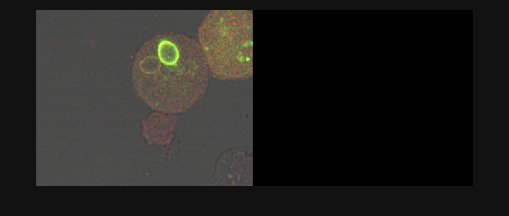

close(v_writer2)


montage({frame, maskedImage});

function [BW,maskedImage] = segmentImage(X)
%segmentImage Segment image using auto-generated code from Image Segmenter app
%  [BW,MASKEDIMAGE] = segmentImage(X) segments image X using auto-generated
%  code from the Image Segmenter app. The final segmentation is returned in
%  BW, and a masked image is returned in MASKEDIMAGE.

% Auto-generated by imageSegmenter app on 26-Apr-2026
%----------------------------------------------------
img_color = X;
X = im2gray(img_color);

% Threshold image with manual threshold
BW = X > 1.809500e+02;

% Fill holes
BW = imfill(BW, 'holes');

% Open mask with default
radius = 3;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% Create masked image.
maskedImage = img_color;
maskedImage(repmat(~BW, 1, 1, 3)) = 0;
end